## Zadanie 6

t = linspace(-1,1,1000);
dt = mean(diff(t));

xt = abs(t); %sygnal, ktory aproksymujemy

g1 = ones(size(t));
g2 = t;
g3 = 3/2*t.^2-1/2;

Liczymy energię sygnałów bazowych jako $E_# =\int_{-\infty \;}^{\infty \;} g_# {\left(t\right)}^2 \mathrm{dt}$

Eg1 = sum(abs(g1).^2)*dt;
Eg2 = sum(abs(g2).^2)*dt;
Eg3 = sum(abs(g3).^2)*dt;

Współczynniki rozwinięcia liczymy jako $A_# =\frac{1}{E_# }\int_{-\infty \;}^{\infty \;} x\left(t\right)g_# \left(t\right)\mathrm{dt}$

A1 = 1/Eg1*sum(xt.*g1)*dt

A1 =            0.5005005005005


A2 = 1/Eg2*sum(xt.*g2)*dt

A2 =      -8.97483885411019e-18


A3 = 1/Eg3*sum(xt.*g3)*dt

A3 =          0.626867511263033


Porównujemy aproksymację naszą metodą z metodą "[fit](https://www.mathworks.com/help/curvefit/fit.html)" wbudowaną w MATLAB. W naszej metodzie $\overset{~}{x\left(t\right)} =A_1 g_1 \left(t\right)+A_2 g_2 \left(t\right)+A_3 g_3 \left(t\right)$.

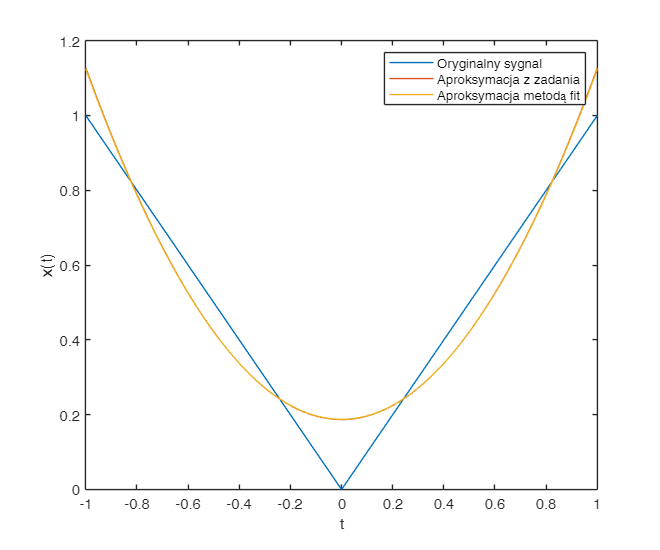

%%
figure;
plot(t,abs(t));
hold on;
plot(t, A1*g1+A2*g2+A3*g3);
eq1 = 'a1+a2*x+a3*((3/2*x^2-1/2))';
f1 = fit(t',abs(t)',eq1);
plot(t,f1(t))
xlabel('t')
ylabel('x(t)')
legend({'Oryginalny sygnal','Aproksymacja z zadania', 'Aproksymacja metodą fit'})

Można policzyć również średniokwadratowy błąd rozwinięcia jako $\Theta =\frac{1}{|a_1 -a_2 |}\int_{a_1 }^{a_2 } {\left\lbrack x\left(t\right)-\overset{~}{x\left(t\right)} \right\rbrack }^2 \mathrm{dt}$

err = 1/diff(minmax(t))*sum((xt-(A1*g1+A2*g2+A3*g3)).^2)*dt

err =        0.00522553264603754
